# EJERCICIO GUERRAS 

clc, clear, clf 
S = rng(12354)

S = struct with fields:
     Type: 'twister'
     Seed: 12354
    State: [625×1 uint32]


### VARIABLES: 

n = 15; % Suministros enviados.
k = 7; % Suministros en la base.
AtaquesB = round(gamrnd(3, 2)); % Cada cuantos días ataca la ciudad B.
TiempoEnvio = randi([3, 6]);  % Tiempo que tarda en llegar el envío (días).
SuministrosPerdidos = round(gamrnd(1,3)); % Número de suministros perdidos cada día.
SuministrosAgotados = round(normrnd(5,2)); % Número de suminstros gastados (semanales).

TPA = AtaquesB;
TPLL = TiempoEnvio;


t = 0 ; % Tiempo ( días ) 
fin = 50; 

sol = [ k ];
semana = [ k ];

### PROGRAMA: 

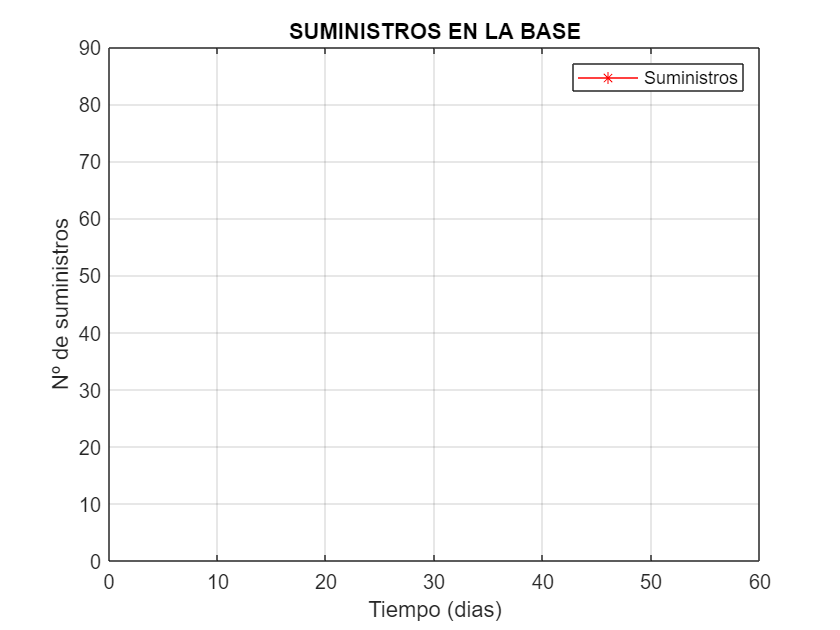

% Rutina de parada 
while t <= fin 

    % Rutina de tiempo 
    t = t + 1;

    if t == TPA

        if TPLL == TPA
            TPLL = TPLL + 1;
        end

        k = k - 5; 
        % kguerra = -k 
        TPA = t + round(gamrnd(3, 2)); 
    end

    if t == TPLL 
        k = k + ( n - SuministrosPerdidos);
        % ksuminstros = n - SuministrosPerdidos
        SuministrosPerdidos = round(gamrnd(1,3));
    end

    resto =  t - floor(t / TPLL ) * TPLL;
    if  resto == 0
        TPLL = t + TiempoEnvio;
        k = k - SuministrosAgotados;
        semana = [ semana k ];
        % kagotados = - SuministrosAgotados
        SuministrosAgotados = round(normrnd(5,2));
    end
  sol = [ sol k ];
  
end

plot(0:fin + 1,sol, '-*r')
hold on
grid on 
xlabel('Tiempo (dias)');
ylabel('Nº de suministros')
title('SUMINISTROS EN LA BASE')
legend('Suministros')

hold off

plot(0:16, semana, '-*')

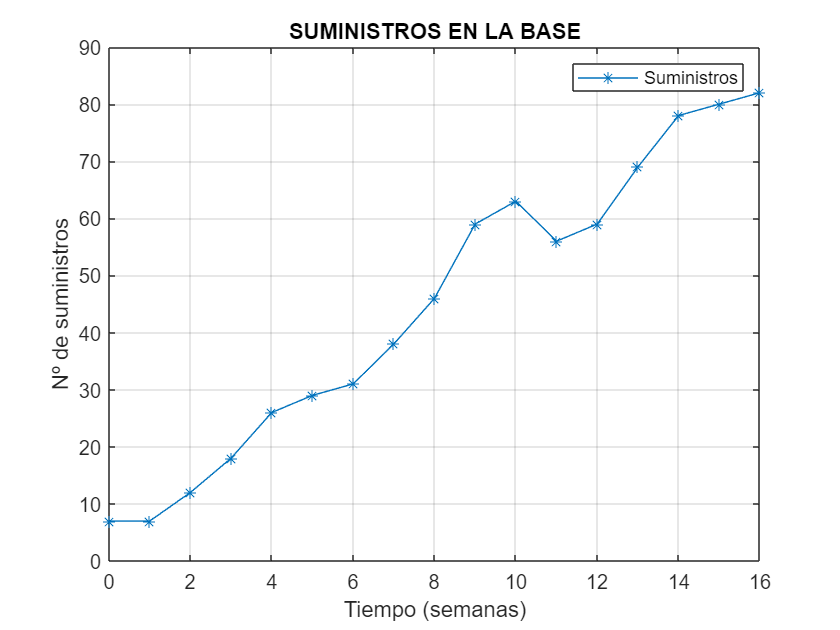

xlabel('Tiempo (semanas)');
ylabel('Nº de suministros')
title('SUMINISTROS EN LA BASE')
legend('Suministros')

hold on 
grid on 